# Big Data Using SQL and Tall Array

Kevin Chng

**Overview :**

This script demonstrates how to access your big data in Microsoft Access and process them using databaseDatastore and tall array in MATLAB. After processing, the result will be saved back to Microsoft Access.

**Highlight/Take Away :** 

- MATLAB allows to exchange data with relational and nonrelational database.

- Automatically coverting between database and MATLAB data type

- Support ODBC-Compliant, JDBC-Compliant Relational datase, NoSQL (Cassandra, MongoDB, and Neo4j)

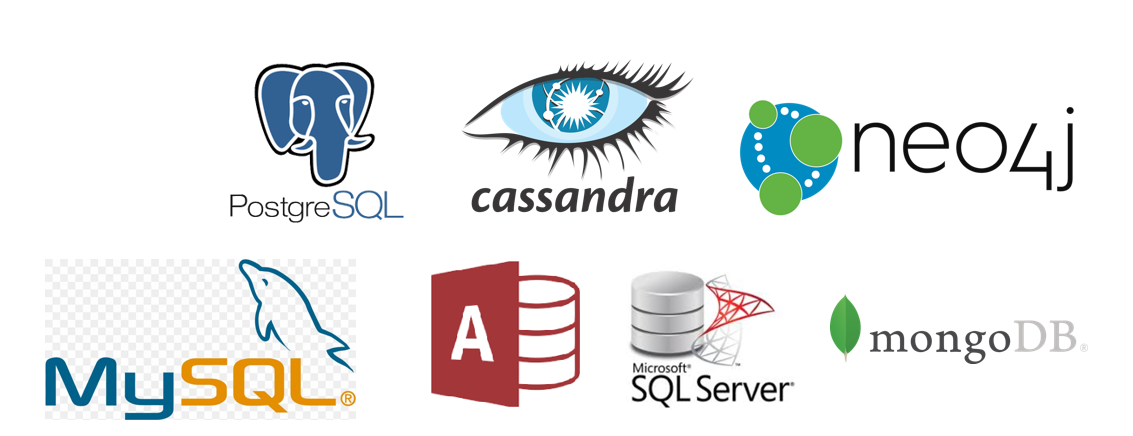

- Database App is available help you to explore the data without writting code, and then generate MATLAB code for automating or operationalizing database workflow.

- For large data workflow, you can split SQL queries and parallelize access to data (With Parallel Computin Toolbox/MATLAB Parallel Server)

- Guildline for Access Relational Database in MATLAB : [https://www.mathworks.com/help/database/ug/access-relational-database-data-in-matlab.html](https://www.mathworks.com/help/database/ug/access-relational-database-data-in-matlab.html)

**Workflow**

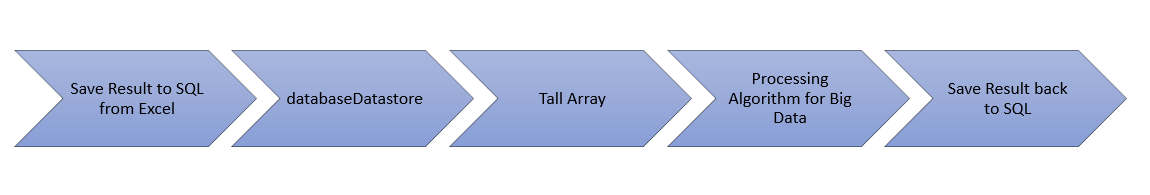

**Prerequisite:**

Install the relevant database driver :

[https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html](https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html)

## 1.0 Clear all the command and workspace

close all;
clear all;
clc;

## 2.0 SQL Data (Read & Write)

- Create SQL Database in Microsoft Access

- Open Database Explorer (MATLAB App) to experience how can you importa data through the App

- Load Data from Excel File

- Write Data to New Table of the Created SQL Database (Hint: You may also write result to new line through SQL insert)]

### 2.1 Create SQL Database in Microsoft Access

- Create table 'y'

- Simply key in some information

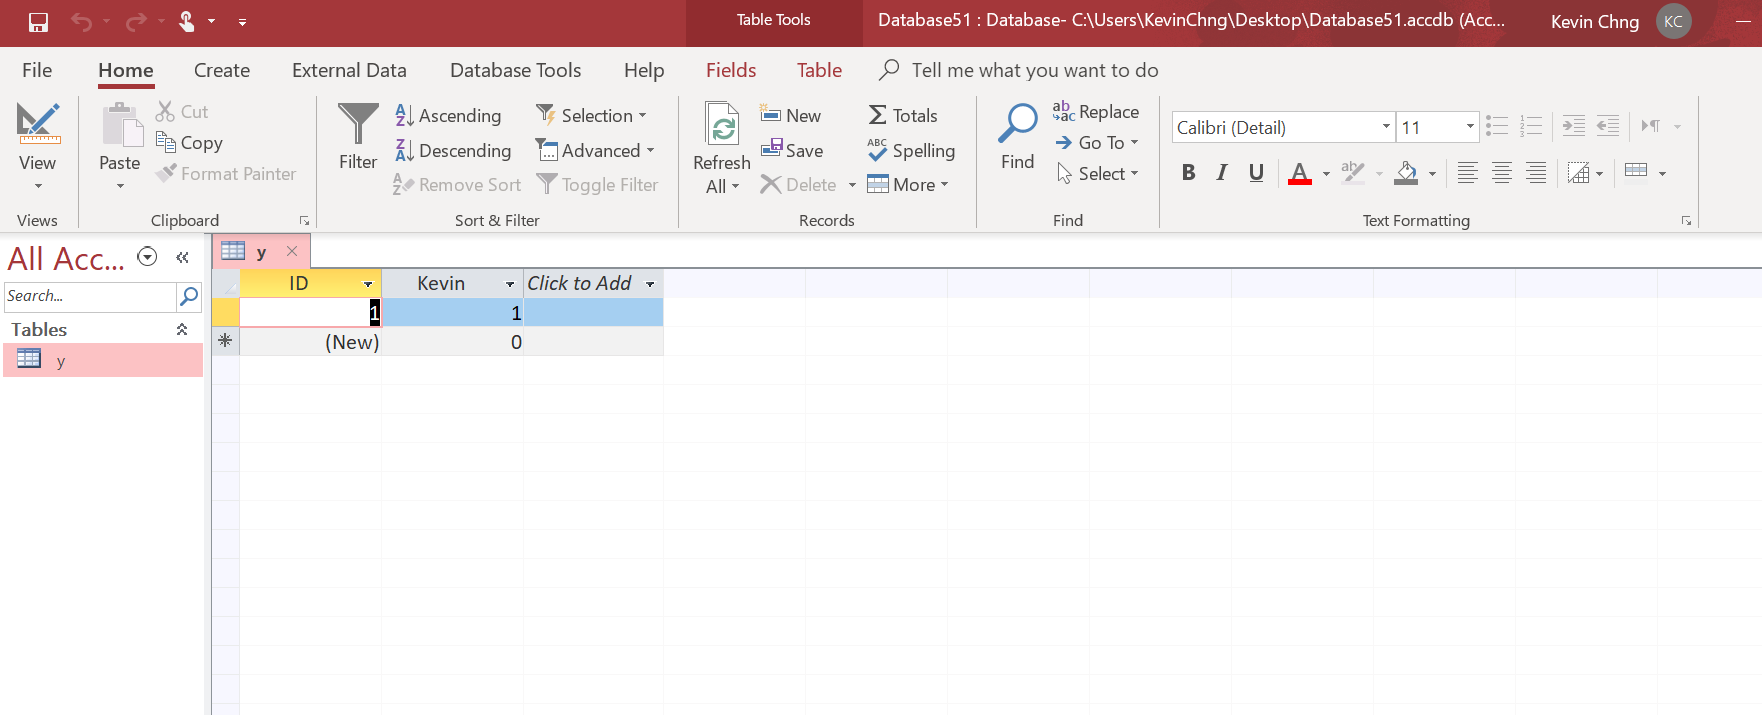

### 2.2 Open Database Explorer (MATLAB App) to experience how can you importa data through the App

- Import the y table created in Microsoft Access

databaseExplorer

### 2.3 Import Data from Excel

Data = importfile("green_tripdata_2016-01.csv");
height_Data = height(Data);
fprintf(sprintf("The Data has %i rows",height_Data));

### 2.4 Connect to SQL and Save Information to SQL (Here we use Microsoft Access SQL)

if you study the code below carefully, you will discover that i'm breaking the code into chunk by chunk saving to Microsoft Access SQL. It is due to memory limitation, if you don't to do the same way as me, you may refer the link below how to execute sql command to save the data from text file to SQL. For this approach, you have to save your data to text file first and subsequently execute sql command in MATLAB to save the data in the text file to SQL database.

Link : [https://www.mathworks.com/help/database/ug/export-data-using-bulk-insert.html](https://www.mathworks.com/help/database/ug/export-data-using-bulk-insert.html)

conn = database('DatabaseTaxi','','');
tablename = 'Green_Trip';
%How many data(rows) you are going to save per iteration

The Data has 1445285 rows

tic
for i=1:1000:height_Data
     if i-1+1000 > height_Data
        sqlwrite(conn,tablename,Data(i:end,:));
     else
        sqlwrite(conn,tablename,Data(i:i-1+1000,:));
     end
     if rem(i-1,100000)==0
         display(sprintf("Progressing : %i iteration",i));
     end
end
toc

    "Progressing : 1 iteration"

    "Progressing : 100001 iteration"

    "Progressing : 200001 iteration"

    "Progressing : 300001 iteration"

    "Progressing : 400001 iteration"

    "Progressing : 500001 iteration"

    "Progressing : 600001 iteration"

    "Progressing : 700001 iteration"

    "Progressing : 800001 iteration"

    "Progressing : 900001 iteration"

    "Progressing : 1000001 iteration"

    "Progressing : 1100001 iteration"

    "Progressing : 1200001 iteration"

    "Progressing : 1300001 iteration"

    "Progressing : 1400001 iteration"



Now, you have save your data from excel to database, howeverm there are more functionality you can play around with SQL in MATLAB. for example, incert more data to existing data, delete data from database, select specify data and specify row and etc.

### More Resources:

- Important function for sql : [database](https://www.mathworks.com/help/database/ug/database.html), [sqlwrite](https://www.mathworks.com/help/database/ug/database.odbc.connection.sqlwrite.html), [sqlread](https://www.mathworks.com/help/database/ug/database.odbc.connection.sqlread.html), [exec](https://www.mathworks.com/help/database/ug/sqlite.exec.html), [fetch](https://www.mathworks.com/help/database/ug/database.odbc.connection.fetch.html), [update](https://se.mathworks.com/help/database/ug/database.odbc.connection.update.html), [rollback](https://se.mathworks.com/help/database/ug/database.odbc.connection.rollback.html), [commit](https://se.mathworks.com/help/database/ug/database.odbc.connection.commit.html)

- With exec and fetch, you can execute sql command to add data, select rows, select column, drop table, delete certain rows and etc.

## 3.0 Read the database using databasedatastore

databaseDatastore : [https://www.mathworks.com/help/database/ug/matlab.io.datastore.databasedatastore.html](https://www.mathworks.com/help/database/ug/matlab.io.datastore.databasedatastore.html)

conn = database('Database51','','');

Elapsed time is 552.643824 seconds.


sqlquery = 'select * from Green_Trip';

dbds = databaseDatastore(conn,sqlquery)
preview(dbds)

## 4.0 Select important factors to analyze

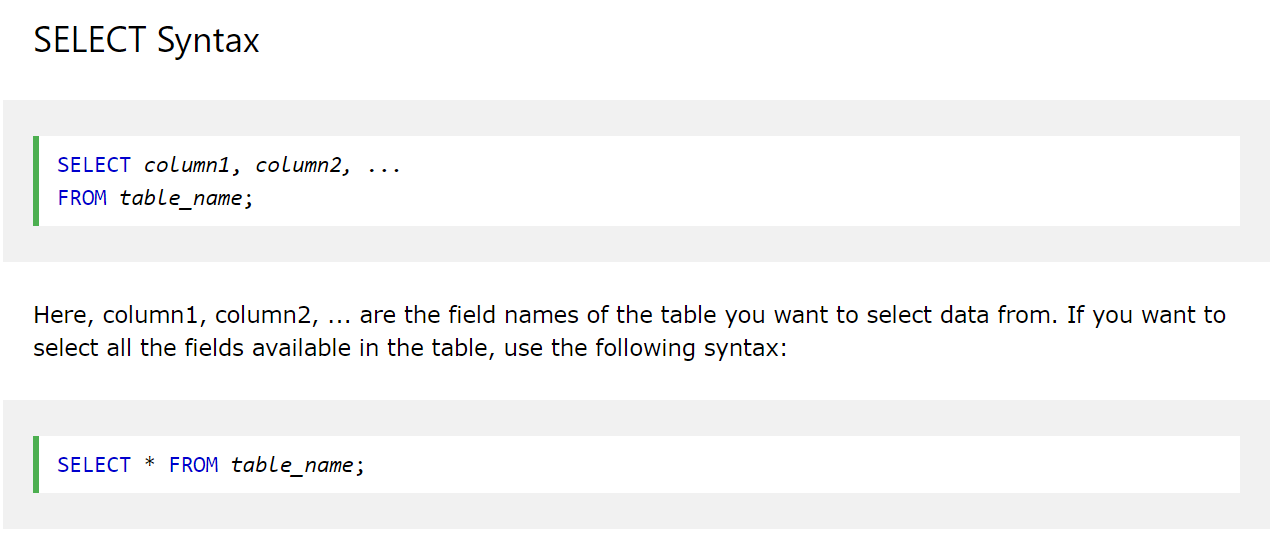

vars = [2,3,11,20,12,15,19]; % green 1 to 6
varnames = dbds.VariableNames(vars);
sqlquery = sprintf('select %s, %s, %s, %s, %s, %s, %s from Green_Trip',varnames{1},varnames{2},varnames{3},varnames{4},varnames{5},varnames{6},varnames{7})
dbds = databaseDatastore(conn,sqlquery)

dbds =   DatabaseDatastore with properties:

       Connection: [1×1 database.odbc.connection]
            Query: 'select * from Green_Trip'
    VariableNames: {1×21 cell}
         ReadSize: 10000


preview(dbds)

ans = 8×21 table
    VendorID     lpep_pickup_datetime       Lpep_dropoff_datetime     Store_and_fwd_flag    RateCodeID    Pickup_longitude    Pickup_latitude    Dropoff_longitude    Dropoff_latitude    Passenger_count    Trip_distance    Fare_amount    Extra    MTA_tax    Tip_amount    Tolls_amount    Ehail_fee     improvement_surcharge    Total_amount    Payment_type    Trip_type
    ________    _______________________    _______________________    __________________    __________    ________________    _______________

You may customize the import with function below :

[https://www.mathworks.com/help/database/ug/database.options.sqlimportoptions.html](https://www.mathworks.com/help/database/ug/database.options.sqlimportoptions.html)

other than sql query, you also can use MATLAB in-built function to select the column variables load into databasedatastore.

opts = databaseImportOptions(conn,tablename);

opts.SelectedVariableNames = varnames;

dbds = databaseDatastore(conn,sqlquery,opts)

## 5.0 Create a tall array

functions support tall array :

tt = tall(dbds);

## 6.0 Create a categorical variable to better represent the data with labels for the payment types.

newCats = {'Credit card', 'Cash', 'No charge', ...
    'Dispute', 'Unknown', 'Voided'};

sqlquery = 'select lpep_pickup_datetime, Lpep_dropoff_datetime, Trip_distance, Payment_type, Fare_amount, Tip_amount, Total_amount from Green_Trip'

tt.Payment_type = categorical(tt.Payment_type,1:6,newCats);

dbds =   DatabaseDatastore with properties:

       Connection: [1×1 database.odbc.connection]
            Query: 'select lpep_pickup_datetime, Lpep_dropoff_datetime, Trip_distance, Payment_type, Fare_amount, Tip_amount, Total_amount from Green_Trip'
    VariableNames: {'lpep_pickup_datetime'  'Lpep_dropoff_datetime'  'Trip_distance'  'Payment_type'  'Fare_amount'  'Tip_amount'  'Total_amount'}
         ReadSize: 10000


## 7.0 Create a new variable in the table with the hour of day of the cab ride. The tall array display shows a preview of the output if possible.

tt.Hr = hour(datetime(tt.lpep_pickup_datetime));

ans = 8×7 table
     lpep_pickup_datetime       Lpep_dropoff_datetime     Trip_distance    Payment_type    Fare_amount    Tip_amount    Total_amount
    _______________________    _______________________    _____________    ____________    ___________    __________    ____________

    {'2016-01-01 00:29:24'}    {'2016-01-01 00:39:36'}        1.46              1                8           1.86          11.16    
    {'2016-01-01 00:19:39'}    {'2016-01-01 00:39:18'}        3.56              2             15.5              0           16.8    
    {'2016-01-01 00:19:33'}    {'2016-01-01 00:39:48'}        3.79              1             16.5           4.45          22.25    
    {'2016-01-01 00:22:12'}    {'2016-01-01 00:38:32'}        3.01              

## 8.0 Perform Simple Calculation

tt.TripDurationMinutes = minute(datetime(tt.Lpep_dropoff_datetime)) - minute(datetime(tt.lpep_pickup_datetime));

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


tt.CostPerMinute = (tt.Total_amount - tt.Tip_amount)./tt.TripDurationMinutes;
tt.TipPercentage = tt.Tip_amount./tt.Fare_amount;
tt.AverageVehicleSpeed = tt.Trip_distance./tt.TripDurationMinutes * 60;

## 9.0 Remove Outliers

%% Remove outliers with logical indexing.
idx = tt.TripDurationMinutes <= .5 | ...    % really short
    tt.TripDurationMinutes >=  60 * 4 | ... % unfeasibly long
    tt.Trip_distance <= .25 | ...            % really short
    tt.Trip_distance >= 1000 | ...           % unfeasibly far
    tt.Fare_amount <= 0 | ...                      % negative fares
    tt.Fare_amount > 1000 | ...                    % unfeasibly large fare 
    any(ismissing(tt),2);                   % missing data     

tt(idx, :) = [];                            % remove entries from array

## 10.0 Use the first 99000 rows to prototype with a subset of data. Depending on the task, we may want a statistical sampling (with datasample), but for now the first part of the data works for our needs.

ttSub = head(tt,30000);

## 11.0 Determine information about each variable by calling summary on all the tall array. This gives you an idea of the nature of the data, size, and number of missing values. In addition, summary passes through the data and retains the information to improve efficiency of future calculations. 

s = summary(ttSub) ;
s.lpep_pickup_datetime 
s.TripDurationMinutes

## 12.0 Visualize the distribution of payment types, from the summary output.

histogram('Categories',s.Payment_type.Categories,...
    'BinCounts',s.Payment_type.Counts)
title('Number of Trips by Payment Type');

## Grouped calculations

vars = {'Trip_distance','Fare_amount','TripDurationMinutes','Hr',...
    'CostPerMinute','Total_amount','Tip_amount','TipPercentage','AverageVehicleSpeed'};

x = ttSub{:,vars};
mn = mean(x,'omitnan')

ans = struct with fields:
           Size: [30000 1]
           Type: 'cell'
    Description: ''
          Units: ''
     Continuity: []


% Perform grouped statistics by hour of day.

ans = struct with fields:
           Size: [30000 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 1
            Max: 58
     NumMissing: 0


statsByHr = grpstats(ttSub(:,vars),'Hr')

## 13.0 Gather results to workspace

[tt1,mn,statsByHr] = gather(ttSub,mn,statsByHr);

## 14.0 Save tt1(New table) to SQL database

- Write to new table in SQL

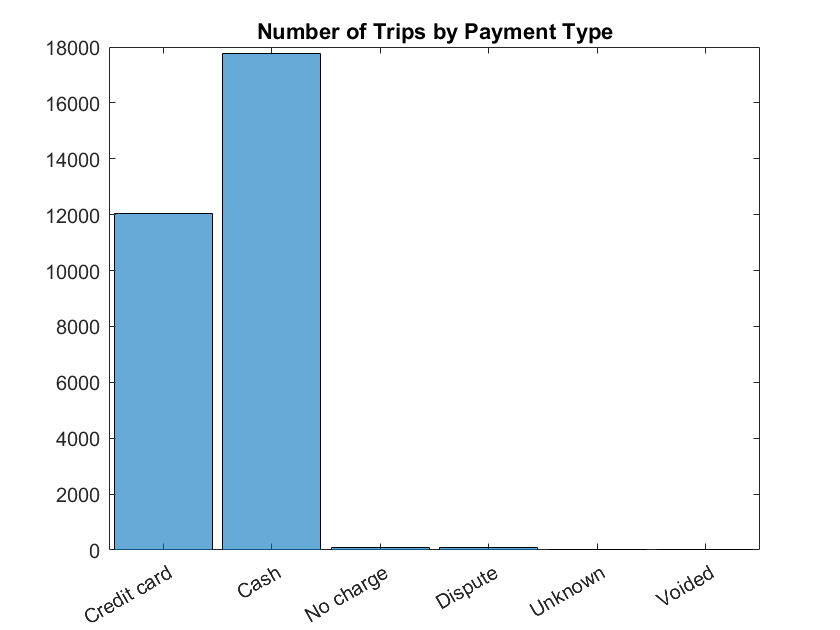

tablename = 'Green_Trip_Result1';

tt1.Payment_type = string(tt1.Payment_type);
tic
for i=1:1:height(tt1)
     sqlwrite(conn,tablename,tt1(i,:));
     if rem(i-1,10000)==0
         fprintf(sprintf("Progressing : %i iteration",i));
     end


mn =

  1×9 tall double row vector

  Columns 1 through 6

   3.046504333333350  12.085130333333332  11.671166666666666   3.191566666666667   1.320198252684446  14.438688999994644

  Columns 7 through 9

   1.066604000000008   0.088348313879315  15.547886782465392



end
toc


statsByHr =

  13×11 tall table

    GroupLabel    Hr    GroupCount    mean_Trip_distance    mean_Fare_amount    mean_TripDurationMinutes    mean_CostPerMinute    mean_Total_amount    mean_Tip_amount     mean_TipPercentage    mean_AverageVehicleSpeed
    __________    __    __________    __________________    ________________    ________________________    __________________    _________________    ________________    __________________    ________________________

      {'0' }       0       4740 

close(conn);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0.096 sec


Progressing : 1 iteration